**kuka iiwa Robotic Arm**

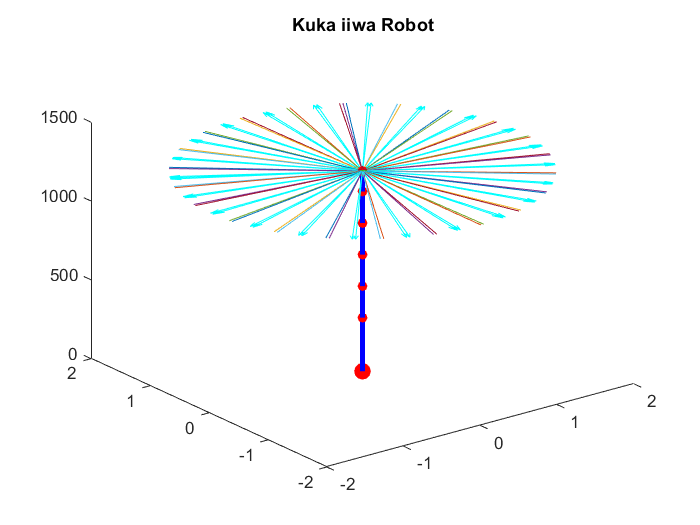

for q1 = 1:2:90
    % length of arm links:
    L = [340 200 200 200 200 126 4];
    q = [0 0 q1 0 0 0 0  0];
    
    [Fk,T] = ForwardKinematics(q,L);
%     display(q1)
    %drawing the Robot Motion:
    draw_myrobot(T)
    %performing theJacobian of the robot:
    Jq = JacobianNumerical(L,deg2rad(q));
end

%Implementing redundant techniques for robot:
%specify the method type (hashJ,PseudoJ,weighted_pseudoJ):
type = "hashJ";
% type = "PseudoJ";
% type = "weighted_pseudoJ";
w=diag([1 1 1 1 1 1 1]);

J_hash = Jacobian_Hash(q,L,w,type)

J =          0         0         0  455.8368         0  111.8090         0
         0 -930.0000         0 -270.3938         0  -66.3230         0
         0         0         0         0         0         0         0
         0    1.0000         0    0.5102         0    0.5102         0
         0         0         0    0.8601         0    0.8601         0
    1.0000         0    1.0000         0    1.0000         0    1.0000


J_hash =    NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN
